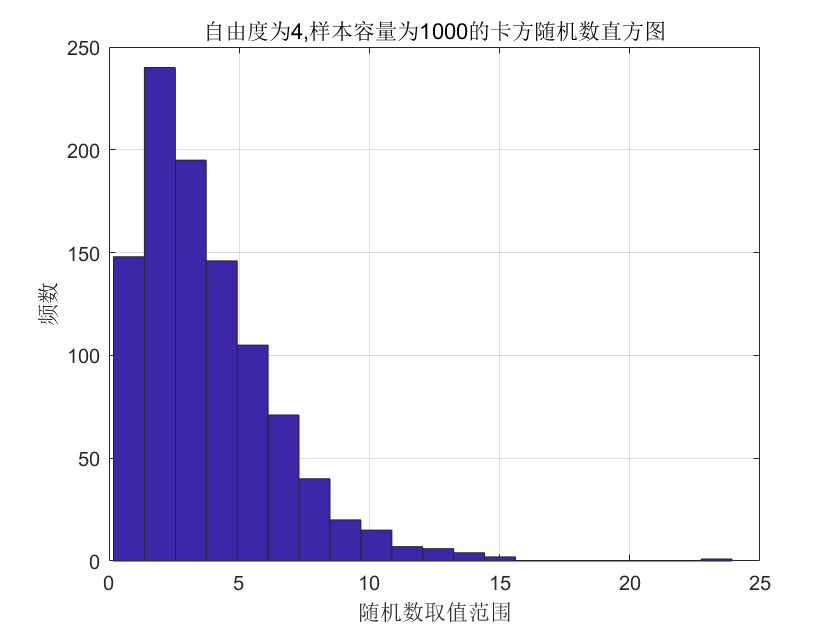

% 实验9 卡方分布随机数
n = 4;      % 自由度
cpc = 1000; % 样本容量
nums = zeros(1, cpc);
for i = 1:cpc
    nums(i) = rndchi2(n);
end
hist(nums, round(cpc / 50));
grid on; axis on;
xlabel("随机数取值范围");
ylabel("频数");
str = sprintf("自由度为%d,样本容量为%d的卡方随机数直方图", n, cpc);
title(str);



% matlab 内置函数有chi2rnd用于生成卡方随机数，在这里就不使用了

function out = rndchi2(n)
% 自由度为n的卡方随机数, 默认返回行向量
x = normrnd(0, 1, 1, n);
out = sum(x .* x);              % 矩阵点乘求和
end